# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder3 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3ICTestData/'];
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(DataFolder3)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo062324/']; % V1D2
MonocuFlag = false;
close all

## 2. Test for different x for E and I; yE and yI kept as 1 -- All killed are folded back

first get basic function information

Too time comsuming. --->> using HPC

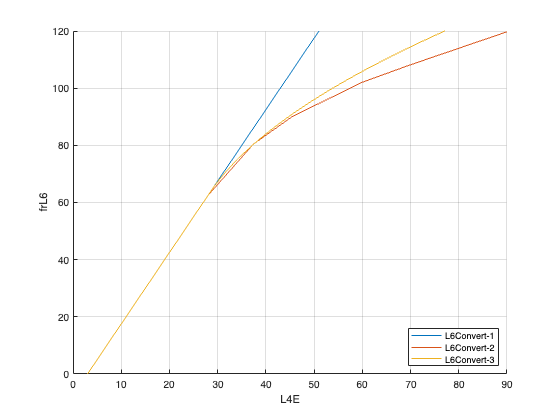

close all
xEAll = 0:0.2:1; xIAll = 0:0.2:1;
lgnSF = 2.5; lgnTF = 10;

ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
L6pars{3} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
L6pars{1} = {2.5,3,62.5,86,86};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118}; % 142.2; 166.7

figure(101)
xx = 0:0.1:100;
hold on
for L6Id = 1:3
    yy = L6Convert(xx,L6pars{L6Id});
    plot(xx,yy,'DisplayName',sprintf('L6Convert-%d',L6Id))
end
grid on
xlim([0 90])
ylim([0 120])
xlabel('L4E')
ylabel('frL6')
legend('Location','SouthEast')


IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKpUse = IKp3;

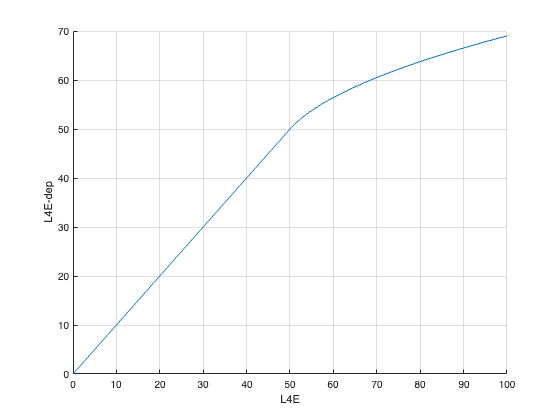

close all
figure(102)
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'}; 

% we are using the L4eL6 conversion curve formula for L4E depression
xx = 0:0.1:220;
hold on
    yy = L6Convert(xx,EKpUse);
    plot(xx,yy,'DisplayName',sprintf('L4E-depression'))
    xlabel('L4E')
ylabel('L4E-dep')
grid on

close all
%Comment = '';
xEInd = 6%:length(xEAll)

xEInd = 6

xIInd = 6

xIInd = 6

fprintf('xE=%.1f, xI=%.1f\n',xEAll(xEInd),xIAll(xIInd))

xE=1.0, xI=1.0


L6parId = 2

L6parId = 2

fprintf('L6 ParameterID %d\n',L6parId)

L6 ParameterID 2


if L6pars{L6parId}{end} == 'quadratic'
    L6Comment = sprintf('%s',L6pars{L6parId}{end})
else
    L6Comment = sprintf('linear')
end

L6Comment = 'linear'

tic
%AngleList = {'0.0'}; % only vertical for now
AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','LARGER'};

## 3. Set up initial conditions

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;

Parameters of L4 kernels

AngleTestAll = 0:7.5:180; % 0:7.5:22.5; % has to be multiples of 7.5
TestNum = length(AngleTestAll); ICTestAll = cell(TestNum,1);
TestExSeq = xEAll(xEInd)*ones(size(0:7.5:180)); TestEySeq = 1*ones(size(TestExSeq));
TestIxSeq = xIAll(xIInd)*ones(size(0:7.5:180)); TestIySeq = 1*ones(size(TestExSeq));

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

ICData = load(sprintf('LDETracesV4D2_NewSmear_ang0.0.mat'));
load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;

LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
for TestId = 1:TestNum
    ICTestAll{TestId} = LDEICOut;
end
LDEOutAll = cell(size(ICTestAll));
NANFlag = false(size(ICTestAll));
%BGFlagAllTest = cell(size(ICTestAll));

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

p = 0.33;% 1-p for the original input
EpocTest = 300;
ExportFlag = 'xn';

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

## Compute NESSs for each angle

TestId = 1;
AngleInpt = AngleTestAll(TestId);

RotInd = floor(AngleInpt/45); % 0-3
MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
switch MirInd % find the corresponding source
    case 0
        AngSource = mod(AngleInpt,45);
    case 1
        AngSource = mod(-AngleInpt,45);
end

% Use the source, decide which response function for angle should I use
AngFuncCtgrCdid = 0:7.5:22.5;
[~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

AngPrint = AngleList{AngFuncCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

L4EmeshXAll = cell(size(DomList));
L4ImeshYAll = cell(size(DomList));
LDEFrfuncAll = cell(size(DomList));
for DomInd = 1:length(DomList)
    FuncTemp = load(sprintf('Func200%s-%s-Ang%s-SF%.1fTF%d-%s.mat',...
        DataPt,Comment,AngPrint,lgnSF,lgnTF,DomList{DomInd}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
    L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
    L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
    LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
LGNlist = 5; L6list = 33;
OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

%OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
if MonocuFlag
    OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;
    SaveStr = ['Mono' Comment];
else
    SaveStr = ['Bino' Comment];
end

L6 kernel

L6ConvSig = 0.75;
L6ConvTruc = 1.5/(L6ConvSig);
Kersize = floor(2*L6ConvSig*L6ConvTruc);
if Kersize<=0
    Kersize= 2; % at least 1
end
[x,y] = meshgrid(1:Kersize,1:Kersize);
c = Kersize/2;
exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
L6Kernel = exp(-exponent);
L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
L6Kernel = L6Kernel + ...
    L6Kernel(end:-1:1,:) + ...
    L6Kernel(:,end:-1:1) + ...
    L6Kernel(end:-1:1,end:-1:1);%symmetrize
L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
L6Kernel(2,2) = 0.3;

LGN and L6 are blurred 

N_HCs = 3; % shrink to 2*2
FigOn = false;
LGNsmear = n_S_HC*0.2;
TruncLGN = 1;
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
    N_HCs,n_S_HC,LGNsmear,TruncLGN,FigOn);

if ~MonocuFlag
    LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
end

PixLGNCtgr = LGNIndSpat_Rec(...
    LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

% symmetrize !! This is actually trick, so I do it ad hoc
PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

completely BG or not?

BGFlag = false;
if BGFlag
    PixL6Ctgr(:,end) = 1; PixL6Ctgr(:,1:end-1) = 0;
    PixLGNCtgr(:,end) = 1; PixLGNCtgr(:,1:end-1) = 0;
end

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

MirInd = logical(MirInd);
CtgrOrder = [2,1;3,4]; % for lower left HC
CtgrOrderUse = rot90(CtgrOrder,RotInd);
if MirInd
    %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
    CtgrOrderUse = flip(CtgrOrderUse,1);
end
CtgrOrderReadout = ...
    [CtgrOrderUse(1,2);
    CtgrOrderUse(1,1);
    CtgrOrderUse(2,1);
    CtgrOrderUse(2,2)];
%    for Ctgr = 1:4
%         PixL6Ctgr(:,Ctgr) = ...
%             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
%         PixLGNCtgr(:,Ctgr) = ...
%             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
%    end

% let's implement something cheap now for 45 deg
PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
ParaIx = TestIxSeq(TestId); ParaIy = TestIySeq(TestId);

C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
    N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

Conn_Reduc_TestS = 6; Conn_Reduc_TestC = 4;
Reduc_S = Conn_Reduc_TestS*(1-CplxR); Reduc_C = Conn_Reduc_TestC*CplxR;
P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

%     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
%
%     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

tic
ICUse = ICTestAll{TestId}; %
IniTest = ICUse;
%IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
%IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
%IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);


start iteration

[LDEOutAll{TestId},LDEIL2Diff{TestId},L2DiffNormNeib{TestId},~,~,FuncUse,...
    NANFlag(TestId)] = ...
    LDEIteration_135FuncMain_CombDom_RealLGNL6(...
    PixLGNCtgr,L6Kernel,IniTest,p,L6pars{L6parId}, EpocTest,...
    C_SS_meanU,C_CS_meanU,C_IS_mean,...
    C_SC_meanU,C_CC_meanU,C_IC_mean,...
    C_SI_mean, C_CI_mean, C_II_mean,...
    L4SEp, L4SIp, ...
    L4CEp, L4CIp, ...
    L4IEp, L4IIp, ...
    L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
    N_HCOutY,NPixX,NPixY,Isaturation,'xn',EKpUse,IKpUse)  ;
LDEEquv = LDEOutAll{TestId}{end};

RunTime = toc;
sprintf('RunTime = %.2f',RunTime)

ans = 'RunTime = 83.51'


if ~NANFlag(TestId)
    for EpcInd = 1:EpocTest+1
        LDEPertRslt = LDEOutAll{TestId}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);

        L2Diff_OneStepAll(TestId,EpcInd) = ...
            sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
    end
end

Comment below if don't need to save data (usually for setting up new NESSs) 

save([SaveToFolder sprintf('ICTest_Paper3-L4EDepression.mat')])
RunTime = toc;
fprintf('RunTime = %.2f',RunTime)

RunTime = 534.06

Use good runs to determine the new fixed point -- only needed when the fixed point is not good enough

close all
load('Paper3LocalTestAll_Rad2_IDRange1-30_h0.60.mat')
%load('Paper3LocalTestAll_Rad-1_IDRange1-30_h0.60.mat')
delId = L2Diff_AllSample(:,1) == 0;
L2Diff_AllSample(delId,:) = [];
LDEPertOutAllSample(delId,:) = [];
LDE_CoG = LDEPertOutAllSample{1};
S_Comp = zeros(size(LDE_CoG.S)); C_Comp = zeros(size(LDE_CoG.C)); I_Comp = zeros(size(LDE_CoG.I));
for SampInd = 1:length(LDEPertOutAllSample)
    S_Comp = S_Comp + LDEPertOutAllSample{SampInd}.S;
    C_Comp = C_Comp + LDEPertOutAllSample{SampInd}.C;
    I_Comp = I_Comp + LDEPertOutAllSample{SampInd}.I;
end
LDE_CoG.S = S_Comp/length(LDEPertOutAllSample);
LDE_CoG.C = C_Comp/length(LDEPertOutAllSample);
LDE_CoG.I = I_Comp/length(LDEPertOutAllSample);
save([SaveToFolder 'LDE_CoG_h0.60_Samp600.mat'],'LDE_CoG');

local convergence plots

Rad = -1; % -2
for h = [0.33 0.5 0.6 0.65 0.7]%
    close all
    %load('Paper3LocalTestAll_Rad-1_IDRange1-300_h0.33.mat')
    %load(sprintf('Paper3LocalTestAll_Rad%d_IDRange1-50_h%.2f.mat',Rad,h))
    load(sprintf('Paper3LocalTestAll-Edep_Rad%d_IDRange1-30_h%.2f.mat',Rad,h))
    delId = L2Diff_AllSample(:,1) == 0;
    L2Diff_AllSample(delId,:) = [];
    LDEPertOutAllSample(delId,:) = [];
    FigLCT = figure('Name','LocalConv','units','normalized',...
        'outerposition',[0,0,0.5,0.5]);
    hold on
    for PlotId = 1:size(L2Diff_AllSample,1)
        plot(L2Diff_AllSample(PlotId,:),'Color',[0.8 0.8 0.8],'LineWidth',0.01,'LineStyle',':')
    end
    grid on
    xlim([0 size(L2Diff_AllSample,2)])
    set(gca,'YScale','log')
    xlabel('iterations')
    ylabel('E-Norm'); title(sprintf('h = %.2f', h))
    % compute mean distances
    % Number of random pairs to compute
    num_pairs = 1000;

    % Store results
    weighted_norms = zeros(num_pairs, 1);
    a = 0.3022;
    for k = 1:num_pairs
        % Randomly select two different indices
        indices = randperm(length(LDEPertOutAllSample), 2);

        % Extract the two structs
        struct1 = LDEPertOutAllSample{indices(1)};
        struct2 = LDEPertOutAllSample{indices(2)};

        % Compute the differences
        diff_S = struct1.S - struct2.S; diff_SHC = reshape(diff_S,80,40); diff_S1HC = diff_SHC(1:10,1:10);
        diff_C = struct1.C - struct2.C; diff_CHC = reshape(diff_C,80,40); diff_C1HC = diff_CHC(1:10,1:10);

        % Compute the weighted 2-norm
        weighted_norms(k) = sqrt(sum((1-a) * diff_S1HC(:) + a * diff_C1HC(:)).^2);
    end

    % Display the results
    title('Mean-Dist of ending states: %f', mean(weighted_norms))


    FigName2 = sprintf('ICTest-Edep-Rad%d-Iter%d-samples%d-h%.2f',...
        Rad,size(L2Diff_AllSample,2),size(L2Diff_AllSample,1),h);
    savefig(FigLCT,[FigurePaperPath FigName2 '.fig']);

    FigLCT.PaperUnits = 'centimeters';
    FigLCT.PaperSize = [36,28];
    FigLCT.PaperOrientation = "landscape";
    exportgraphics(FigLCT,[FigurePaperPath FigName2 '.pdf'],'Resolution',150)
    close all
end

rate maps for non-convergence

Rad = -1; % -2
hAll = [0.33 0.5 0.6 0.65 0.7]%

hAll =     0.3300    0.5000    0.6000    0.6500    0.7000


close all
h = hAll(5)

h = 0.7000

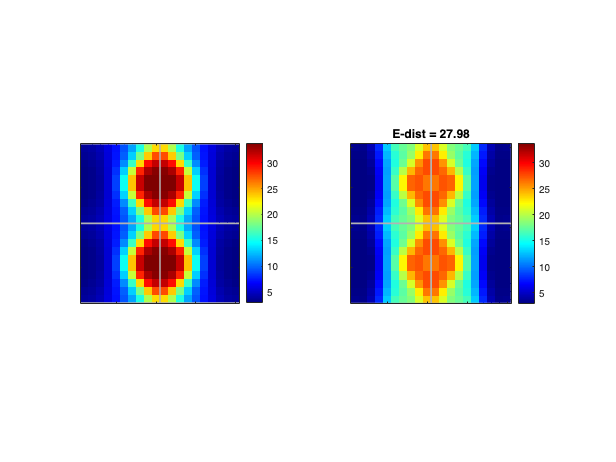

%load('Paper3LocalTestAll_Rad-1_IDRange1-300_h0.33.mat')
%load(sprintf('Paper3LocalTestAll_Rad%d_IDRange1-50_h%.2f.mat',Rad,h))
load(sprintf('Paper3LocalTestAll-Edep_Rad%d_IDRange1-30_h%.2f.mat',Rad,h))
delId = L2Diff_AllSample(:,1) == 0;
L2Diff_AllSample(delId,:) = [];
LDEPertOutAllSample(delId,:) = [];
LDE_end = LDEPertOutAllSample{1};

struct1 = LDE_end;
load([SaveToFolder 'LDE_CoG_h0.60_Samp600.mat'],'LDE_CoG');
struct2 = LDE_CoG;
% Compute the differences
diff_S = struct1.S - struct2.S; diff_SHC = reshape(diff_S,80,40); diff_S1HC = diff_SHC(1:10,1:10);
diff_C = struct1.C - struct2.C; diff_CHC = reshape(diff_C,80,40); diff_C1HC = diff_CHC(1:10,1:10);

% Compute the weighted 2-norm
E_norm1 = sqrt(sum((1-a) * diff_S1HC(:) + a * diff_C1HC(:)).^2);
figure(103)
subplot 121
ShowField_Rec(struct2.S*(1-a) + struct2.C*a, 1:3200,40,80)
axis([0.5 20.5 10.5 30.5]); axis square

subplot 122
ShowField_Rec(LDE_end.S*(1-a) + LDE_end.C*a, 1:3200,40,80)
title(sprintf('E-dist = %.2f',E_norm1))
axis([0.5 20.5 10.5 30.5]); axis square
minc = min(struct2.S*(1-a) + struct2.C*a,[],'all');
maxc = max(struct2.S*(1-a) + struct2.C*a,[],'all');
clim([minc maxc])